### 线性变换法设计 IIR 数字低通滤波器

clc
clear
close all

fStepSignal2 = 3.1416


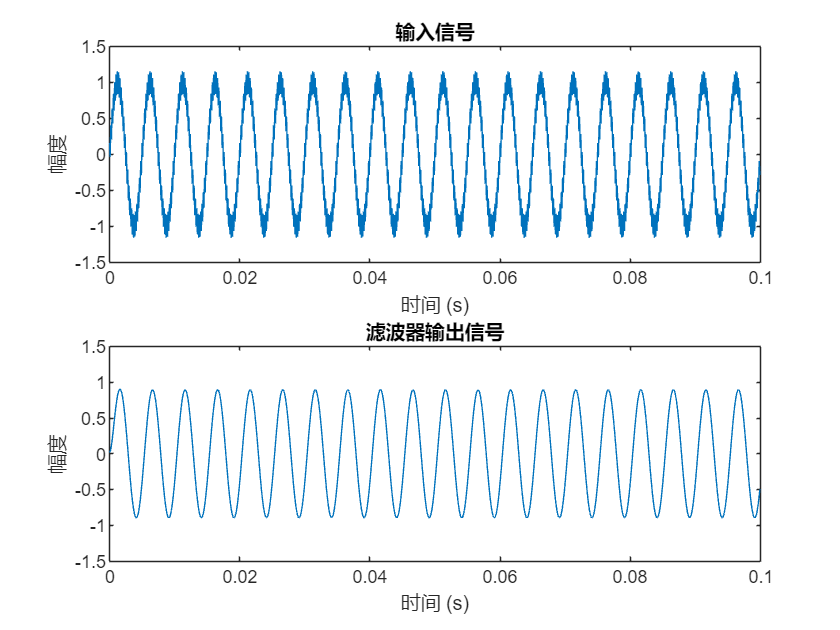

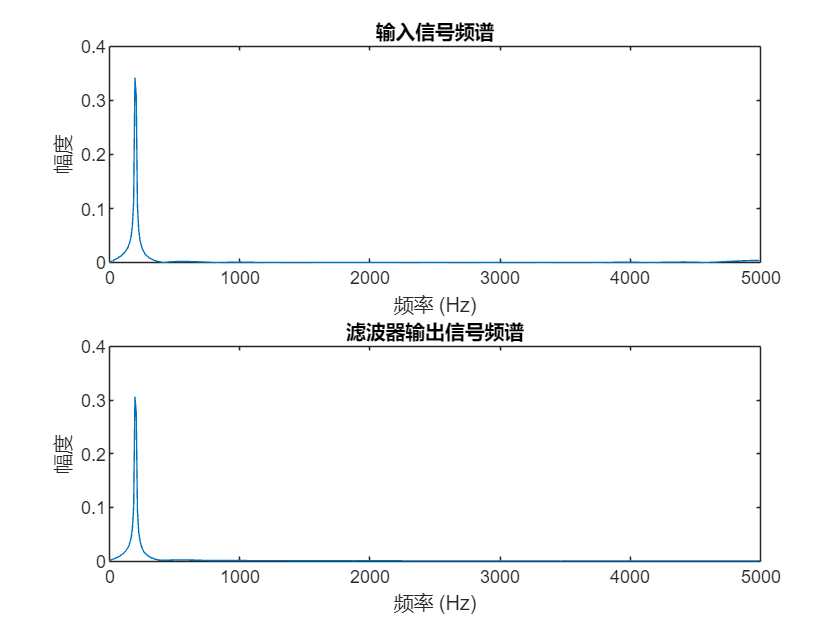

fStepSignal2 = 2.0944


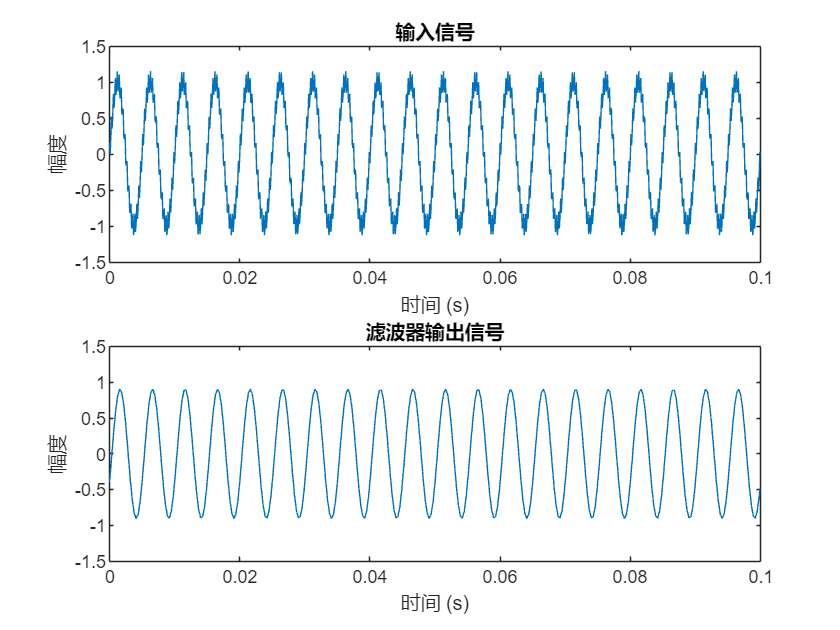

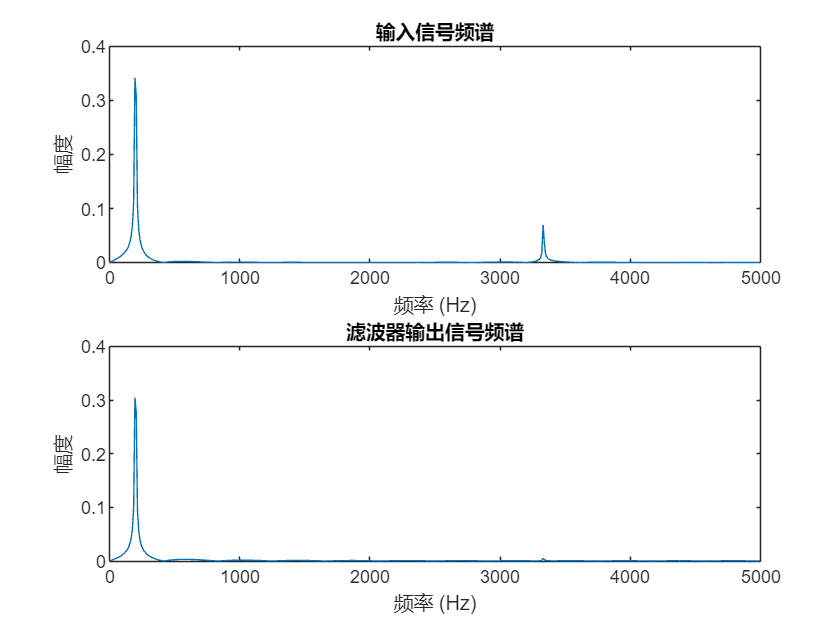

fStepSignal2 = 1.5708


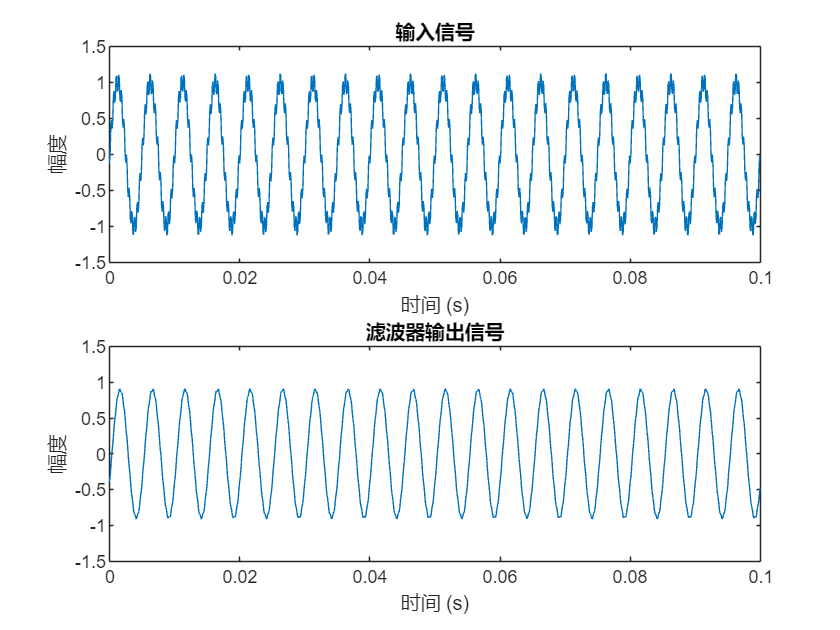

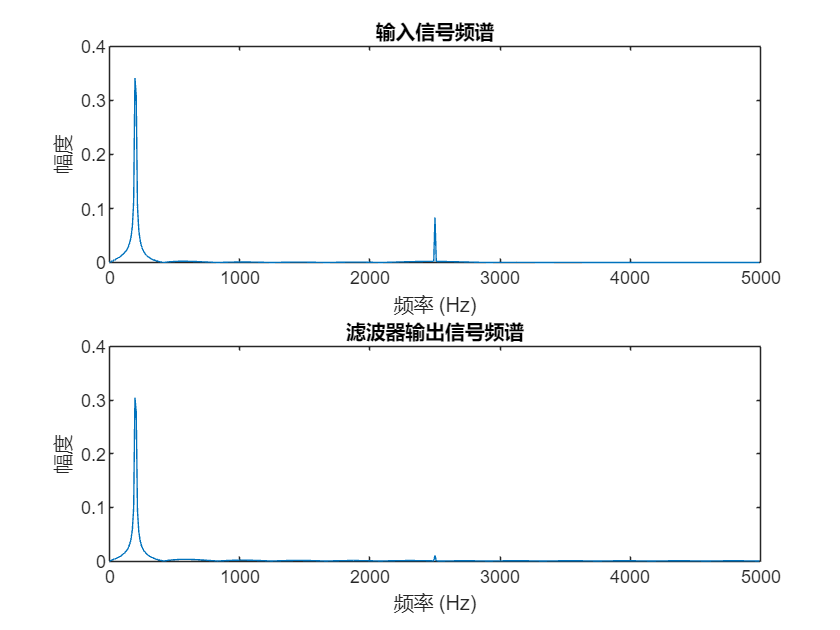

fStepSignal2 = 1.2566


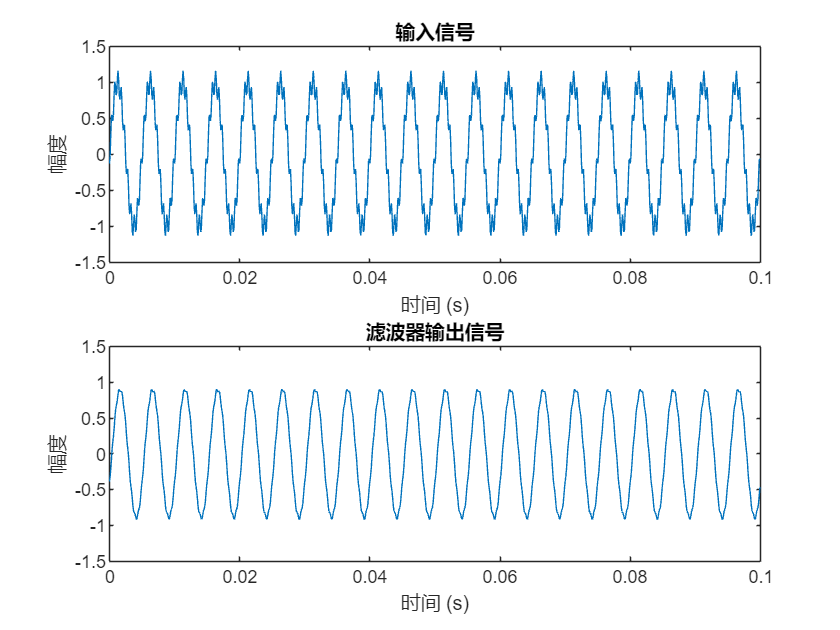

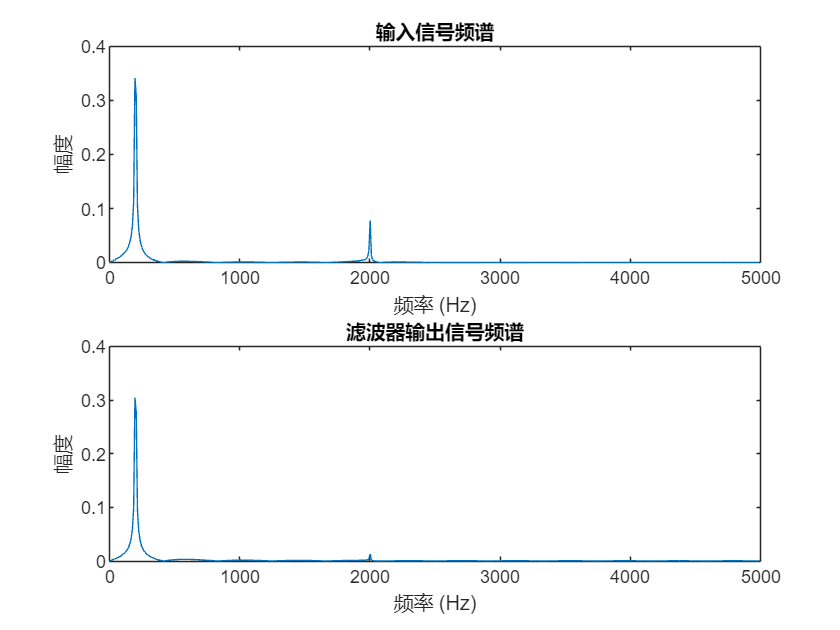

fStepSignal2 = 1.0472


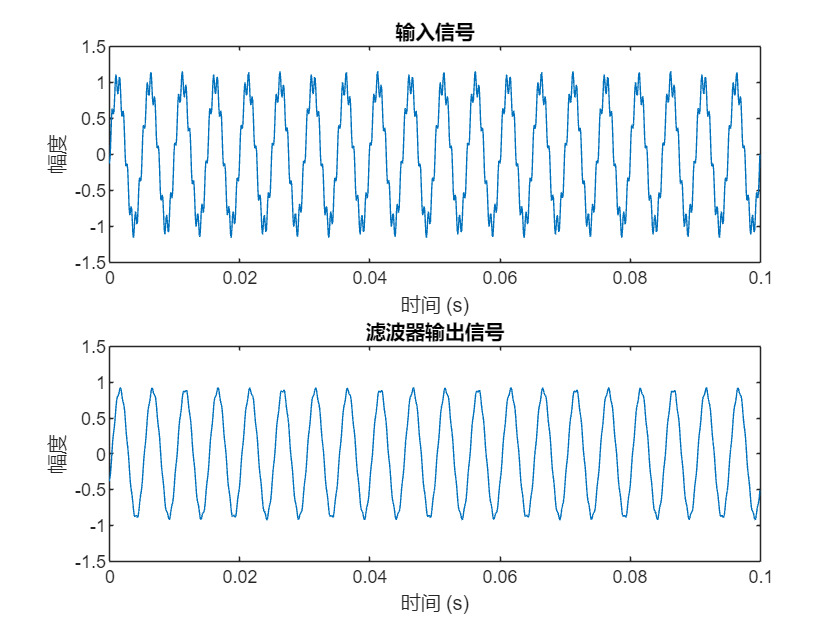

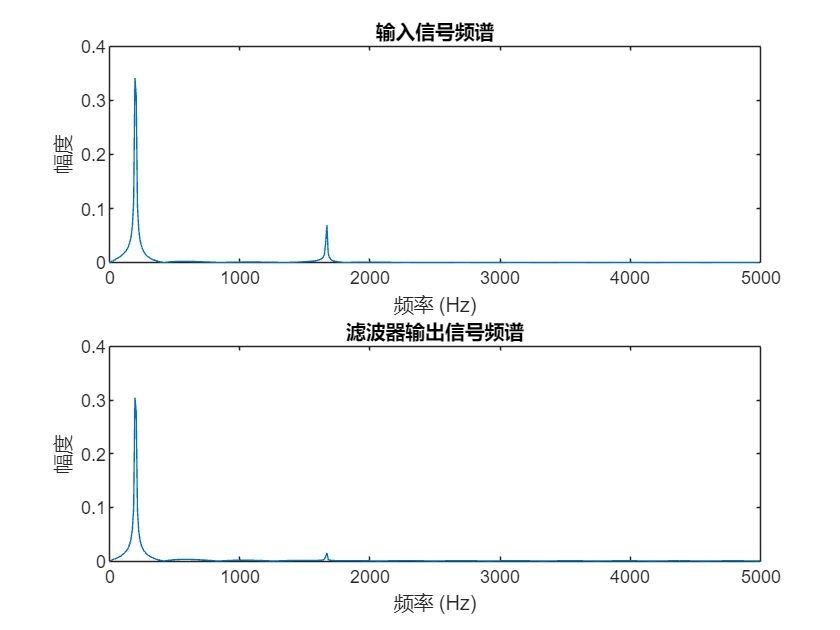

% 参数设置
IIRNUMBER = 2;         % 滤波器阶数
SAMPLEF = 10000;       % 采样频率 (Hz)
PI = pi;

% 滤波器系数
fBn = [0.0, 0.7757];   % 反馈系数
fAn = [0.1122, 0.1122];% 前馈系数

% 滤波器状态 (延迟线)
fXn = zeros(1, IIRNUMBER); % 输入信号历史值
fYn = zeros(1, IIRNUMBER); % 输出信号历史值

% 信号生成参数
fSignal1 = 0.0;                % 信号1初始相位
fSignal2 = PI * 0.1;           % 信号2初始相位
fStepSignal1 = 2 * PI / 50;    % 信号1相位步长 (对应200 Hz)
% fStepSignal2 = 2 * PI / 5;     % 信号2相位步长 (对应2000 Hz)
fStepSignal2 = [2*PI/2,2*PI/3, 2*PI/4,2*PI/5, 2*PI/6]; %更改fStepSignal2的值

% 缓冲区设置
BUFFER_SIZE = 256;      % 缓冲区大小
fIn = zeros(1, BUFFER_SIZE);  % 输入信号缓冲区
fOut = zeros(1, BUFFER_SIZE); % 输出信号缓冲区
nIn = 1; nOut = 1;      % 缓冲区索引

% 模拟输入和滤波处理
NUM_ITER = 1000;        % 总采样点数
inputSignal = zeros(1, NUM_ITER); % 用于记录输入信号
outputSignal = zeros(1, NUM_ITER);% 用于记录输出信号

for m = 1:length(fStepSignal2)
    disp("fStepSignal2 = " + num2str(fStepSignal2(m)))
    for k = 1:NUM_ITER
        % 生成输入信号
        fXn(1) = sin(fSignal1) + cos(fSignal2) / 6.0;

        % 更新信号相位
        fSignal1 = fSignal1 + fStepSignal1;
        if fSignal1 >= 2 * PI
            fSignal1 = fSignal1 - 2 * PI;
        end
        fSignal2 = fSignal2 + fStepSignal2(m);
        if fSignal2 >= 2 * PI
            fSignal2 = fSignal2 - 2 * PI;
        end

        % 保存到缓冲区
        fIn(nIn) = fXn(1);
        nIn = mod(nIn, BUFFER_SIZE) + 1; % 循环缓冲区索引

        % IIR 滤波器计算
        fSum = 0.0;
        for i = 1:IIRNUMBER
            fSum = fSum + fXn(i) * fAn(i) + fYn(i) * fBn(i);
        end
        fYn(1) = fSum; % 滤波器当前输出

        % 更新延迟线
        for i = IIRNUMBER:-1:2
            fXn(i) = fXn(i-1);
            fYn(i) = fYn(i-1);
        end

        % 保存滤波器输出到缓冲区
        fOut(nOut) = fSum;
        nOut = mod(nOut, BUFFER_SIZE) + 1; % 循环缓冲区索引

        % 保存结果到数组
        inputSignal(k) = fXn(1);
        outputSignal(k) = fSum;
    end

    % 绘图
    t = (0:NUM_ITER-1) / SAMPLEF; % 时间轴
    figure;
    subplot(2, 1, 1);
    plot(t, inputSignal);
    title('输入信号');
    xlabel('时间 (s)');
    ylabel('幅度');
    ylim([-1.5,1.5]);

    subplot(2, 1, 2);
    plot(t, outputSignal);
    title('滤波器输出信号');
    xlabel('时间 (s)');
    ylabel('幅度');
    ylim([-1.5,1.5]);

    % 计算频谱
    NFFT = 2^nextpow2(NUM_ITER); % 为提高频谱分辨率，对点数扩展到最近的2的幂
    freqAxis = SAMPLEF * (0:(NFFT/2)-1) / NFFT; % 频率轴

    % 输入信号频谱
    inputSpectrum = abs(fft(inputSignal, NFFT) / NUM_ITER);
    inputSpectrum = inputSpectrum(1:NFFT/2); % 取一半频谱 (正频率部分)

    % 输出信号频谱
    outputSpectrum = abs(fft(outputSignal, NFFT) / NUM_ITER);
    outputSpectrum = outputSpectrum(1:NFFT/2); % 取一半频谱 (正频率部分)

    % 绘制频谱
    figure;
    subplot(2, 1, 1);
    plot(freqAxis, inputSpectrum);
    title('输入信号频谱');
    xlabel('频率 (Hz)');
    ylabel('幅度');
    ylim([0,0.4]);

    subplot(2, 1, 2);
    plot(freqAxis, outputSpectrum);
    title('滤波器输出信号频谱');
    xlabel('频率 (Hz)');
    ylabel('幅度');
    ylim([0,0.4]);
end